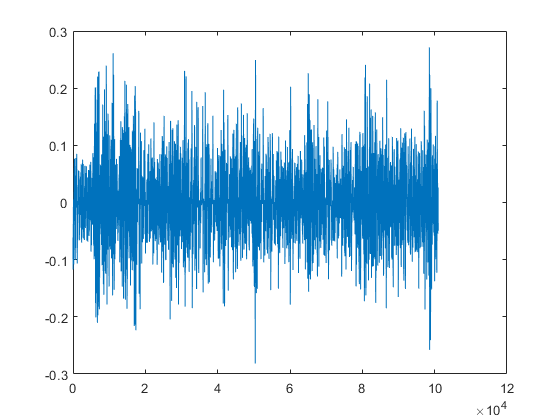

clear;
close all;
clc;
format long;

dirname = 'sample13/';
outname = [dirname, 'enhan.wav'];
orig_outname = [dirname, 'orig_enhan.wav'];
paths = csvimport([dirname, 'wav.list'],'columns', {'path'});

[x1, sr] = audioread(paths{1});
[x2, sr] = audioread(paths{2});
[x3, sr] = audioread(paths{3});
[x4, sr] = audioread(paths{4});
[x5, sr] = audioread(paths{5});

x = [x1, x2, x3, x4, x5];
x = x';
nsample = size(x,2);
nmic = 5;
%npair = nmic - 1;
npair = nmic;

figure;plot(x(1,:));

## make hamming window

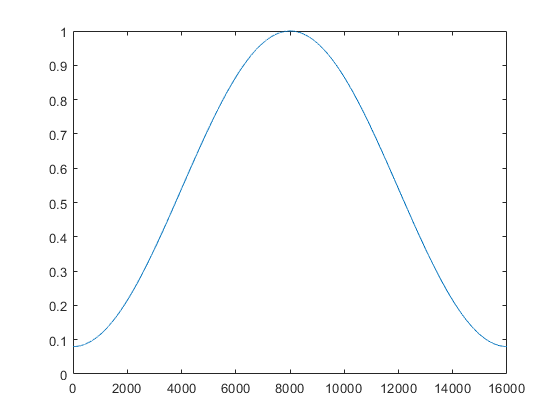

nwin = 16000; % 1 sec
%     hamm_val = 0.54 - 0.46*cos(6.283185307*i/(window-1));
win = zeros(1,nwin);
for i = 1:nwin
    win(i) = 0.54 - 0.46 * cos(6.283185307*(i-1)/(nwin-1));
end

figure; plot(win);

disp(win(1:10));

  1 ~ 3번 열

   0.080000000000000   0.080000035473324   0.080000141893292

  4 ~ 6번 열

   0.080000319259887   0.080000567573081   0.080000886832836

  7 ~ 9번 열

   0.080001277039103   0.080001738191823   0.080002270290922

  10번 열

   0.080002873336321



## testing calculating xcorr

npiece = 200;
nfft = 16384*2;
nbest = 2;
nmask = 5;
scroll = floor(nsample / (npiece+2)); 

stft1 = fft([x(1,scroll+1:(scroll+nwin)) .* win, zeros(1,nfft-nwin)]); 
stft2 = fft([x(2,scroll+1:(scroll+nwin)) .* win, zeros(1,nfft-nwin)]); 

numerator = stft1 .* conj(stft2);
ccorr = real(ifft(numerator ./ (abs(numerator))));
ccorr = [ccorr(end-479:end), ccorr(1:480)];

[best_ccorr, best_idx] = maxk(ccorr, nbest, nmask);
disp(scroll);

   499



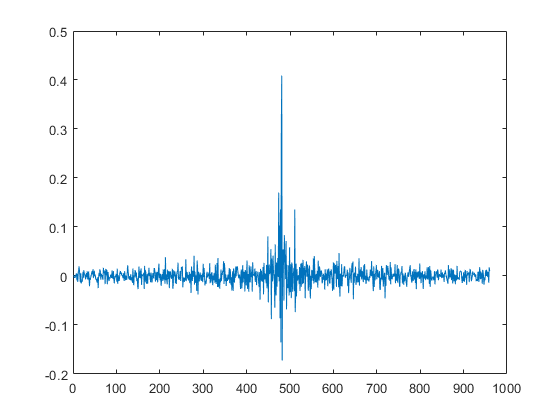

plot(ccorr);


disp(best_ccorr);

   0.408958456301195
   0.170130432940018



## calculate avg_ccorr

avg_ccorr = zeros(nmic, nmic);


for i = 1:npiece
    st = i * scroll + 1;
    ed = st + 16000 - 1;
    if st + 16384 >= nsample
        break;
    end

    for m1 = 1:(nmic-1)
        avg_ccorr(m1, m1) = 0;
        for m2 = (m1+1):nmic
            stft1 = fft([x(m1,st:ed) .* win, zeros(1,nfft-nwin)]); 
            stft2 = fft([x(m2,st:ed) .* win, zeros(1,nfft-nwin)]);
            numerator = stft1 .* conj(stft2);
            ccorr = real(ifft(numerator ./ (abs(numerator))));
            ccorr = [ccorr(end-479:end), ccorr(1:480)];

            maxk_val = sum(maxk(ccorr, nbest, nmask));
            
            avg_ccorr(m1, m2) = avg_ccorr(m1, m2) + (maxk_val);
            avg_ccorr(m2, m1) = avg_ccorr(m1, m2); 
        end
    end
end

avg_ccorr = avg_ccorr / (nbest * npiece);

disp(avg_ccorr);

  1 ~ 3번 열

                   0   0.135171215716803   0.160113571051483
   0.135171215716803                   0   0.147598937278829
   0.160113571051483   0.147598937278829                   0
   0.149326902449198   0.136158993697480   0.151467323063602
   0.133187537736043   0.162286822562546   0.141489292039026

  4 ~ 5번 열

   0.149326902449198   0.133187537736043
   0.136158993697480   0.162286822562546
   0.151467323063602   0.141489292039026
                   0   0.169006527129801
   0.169006527129801                   0



fprintf('%.8f\n', sum(avg_ccorr/nmic));

0.11555985
0.11624319
0.12013382
0.12119195
0.12119404


disp(sum(avg_ccorr,1));

  1 ~ 3번 열

   0.577799226953528   0.581215969255658   0.600669123432940

  4 ~ 5번 열

   0.605959746340081   0.605970179467416



disp(sum(avg_ccorr,1)/nmic);

  1 ~ 3번 열

   0.115559845390706   0.116243193851132   0.120133824686588

  4 ~ 5번 열

   0.121191949268016   0.121194035893483




[dummy, ref_mic] = max(sum(avg_ccorr));

disp(ref_mic); 

     5



## calculating scaling factor

nsegment = 10;

max_val = zeros(nmic, 1);

if size(x,2) <= 160000 % 10 seconds
    for m = 1:nmic
        max_val(m) = max(abs(x(m,:)));
    end
else
    if size(x,2) < 1600000 % 100 seconds
        nsegment = floor(size(x,2) / 160000);
    end
    
    scroll = floor(size(x,2) / nsegment);
    max_val_candidate = zeros(nmic, nsegment);
    
    for s = 0:(nsegment-1)
        st = s * scroll + 1;
        ed = st + 160000 - 1;
        for m = 1:nmic
            max_val_candidate(m,s+1) = max(abs(x(m,st:ed)));
        end
    end
    
    for m = 1:nmic
        
        sorted = sort(max_val_candidate(m,:), 'ascend');
        if length(sorted(:)) > 2
            max_val(m) = sorted(end/2 + 1);
        else
            max_val(m) = sorted;
        end
    end
end

overall_weight = (0.3 * nmic) / sum(max_val);

disp(max_val');

  1 ~ 3번 열

   0.281707763671875   0.154968261718750   0.108764648437500

  4 ~ 5번 열

   0.166870117187500   0.161895751953125



disp(overall_weight);

   1.715841653284926



## compute total number of delays

% int totalNumDelays
% % = (int)((m_frames - (*m_config).windowFrames - m_biggestSkew - m_UEMGap)/((*m_config).
% rate*m_sampleRateInMs));
% sr_in_ms = 16000 / 1000; % 16

% too complicated. I should do hard coding
nframe = floor(( nsample - 8000 ) / (4000));

disp(nframe);

    23



## recreating hamming window

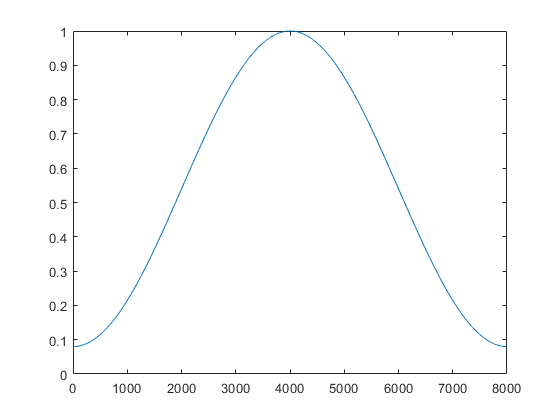

nwin = 8000; % 0.5 sec
nfft = 16384;

win = zeros(1,nwin);
for i = 1:nwin
    win(i) = 0.54 - 0.46 * cos(6.283185307*(i-1)/(nwin-1));
end

figure; plot(win);

% Marginst for delays in frames: 480 in ms: 30
disp(16000 * 30 / 1000);

   480



## compute TDOA

nbest = 4;

micpair = zeros(nmic, npair);

gcc_nbest = zeros(npair, nframe, nbest);
tdoa_nbest = zeros(npair, nframe, nbest);
lrfilp_gcc = zeros(npair, nframe, nfft);

for m = 1:nmic
    p = 1; % pair idx
    for i = 1:nmic

        micpair(m,p) = i;
        p = p + 1;
    end
end


for t = 1:(nframe)
    st = (t-1) * 4000 + 1;
    ed = st + nwin - 1;

        for p = 1:npair
            
            m = micpair(ref_mic,p);
            
            stft_ref = fft([x(ref_mic,st:ed) .* win, zeros(1,nfft-nwin)]); 
            stft_m = fft([x(m,st:ed) .* win, zeros(1,nfft-nwin)]);
            numerator = stft_m .* conj(stft_ref);
            gcc = real(ifft(numerator ./ (eps+abs(numerator))));
            gcc = [gcc(end-479:end), gcc(1:480)];
            [gcck, tdoak] = maxk(gcc, nbest, nmask);
            gcc_nbest(p,t,:) = gcck;
            tdoa_nbest(p,t,:) = tdoak;
            tdoa_nbest(p,t,:) = tdoa_nbest(p,t,:) - (481); % index shifting
          
        end

end

disp(squeeze(gcc_nbest(:,:,1)));

  1 ~ 3번 열

   0.292582323566952   0.349700343331565   0.335024026553501
   0.523848262862563   0.560079353750408   0.367787019058493
   0.306599361065787   0.356399129734748   0.307279098777694
   0.539332968962124   0.610718972858051   0.417161473466042
   0.999999999981291   0.999999999991188   0.999999999984111

  4 ~ 6번 열

   0.468093211686416   0.333481006699875   0.180254742873789
   0.479092646460969   0.249891158704947   0.191068195286834
   0.406290403112857   0.320766943021805   0.155382124584237
   0.576061351495064   0.423814437735148   0.195637671486840
   0.999999999990342   0.999999999941400   0.999999999966652

  7 ~ 9번 열

   0.311962688045702   0.168889396993656   0.139348098121120
   0.305465445923937   0.271522466907849   0.304264268407095
   0.276017238601162   0.152923133454386   0.255383581416543
   0.387549313726641   0.165574417475587   0.286769149075923
   0.999999999994618   0.999999999999203   0.999999999989106

  10 ~ 12번 열

   0.111172628356052   0.1818455

disp(squeeze(gcc_nbest(:,:,2)));

  1 ~ 3번 열

   0.124473303001084   0.124488181068975   0.131656772874901
   0.115319656237522   0.114323734751770   0.109644413015412
   0.114858309918926   0.133089160513524   0.110326915127370
   0.111722275300006   0.105245279196093   0.067748669549198
   0.000000000018492   0.000000000008711   0.000000000015133

  4 ~ 6번 열

   0.116275617621250   0.075101060316377   0.076895206905888
   0.113059464584554   0.087798864506915   0.124533313286524
   0.108766998873631   0.102269246629569   0.105029633025220
   0.166615826063135   0.082611883453946   0.087455235388818
   0.000000000009608   0.000000000058139   0.000000000033147

  7 ~ 9번 열

   0.124117031884074   0.090769157070504   0.080192675051501
   0.079100139919515   0.074918148619750   0.064448859007446
   0.171773595649852   0.087007107841400   0.095677256666363
   0.133136618349186   0.060674614720911   0.079826801490598
   0.000000000005341   0.000000000000644   0.000000000010675

  10 ~ 12번 열

   0.070122909563409   0.0788271


disp(squeeze(tdoa_nbest(:,:,1)));

  1 ~ 12번 열

     0     0     0     0     0     0     0     0     2     0     0     0
     1     1     1     1     0     0     0     0     0     0    -1     0
    -1    -1    -1    -1    -1     2     2    -1    -1     2     0    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1    -1
     0     0     0     0     0     0     0     0     0     0     0     0

  13 ~ 23번 열

     0   -58    -1     0     0     3     3     1     1     1     1
     0     0    -1     0     0     0     0     0     0     1     1
    -8    -7     0     0     0     3     0     0     0     0     0
     1     1     1    -1    -1     1     1    -1    -1     0     2
     0     0     0     0     0     0     0     0     0     0     0



disp(squeeze(tdoa_nbest(:,:,2)));

  1 ~ 12번 열

    -6    31    -6    -6   -36    -7    -7   -24    10  -124    10    -7
   -36     8    -6   -35   -35    -8     5     5    -8    -8     8   -37
    -9   -38    -7    -7    -9    -3    -5     4    -8    -8    -7   -38
   -38   -38    -8    -8   -37    -9    -8   -14     5    -4   -18    -8
     5     5     5    -5     5    -5     5     5     5    -5    -5     5

  13 ~ 23번 열

    -7     3   -49    -6    90    55    -8    -4   -29    -6    -6
     6    -8   -15    -6    -6    -8    -8    -6     6    -6     8
    -1    -2   -10    -8    -5    -8    -6    -6    -7    -8    -8
    -4    -5   -46    -8    -8    -4    -5     4     4   -38    -5
    -5    -5    -5     5    -5     5     5     9     5     5     5



## find noise threshold

th_idx = floor((0.1 * nframe)) + 1;

sorted = sort(sum(gcc_nbest(:,:,1),1) - sum(gcc_nbest(ref_mic,:,1),1), 'ascend');

threshold = sorted(th_idx)/(nmic-1);

% Computing the optimum delays
disp(threshold);

   0.150911321354500



## noise filtering

noise_filter = zeros(npair, nframe);

for p = 1:npair
    for t = 1:nframe
        if gcc_nbest(p,t,1) < threshold
            noise_filter(p,t) = 1;
            if t == 1  % it's silence
                gcc_nbest(p,t,:) = 0; % masking with discouraging values
                gcc_nbest(p,t,1) = 1; % only one path
                tdoa_nbest(p,t,:) = 480; % masking with discouraging values
                tdoa_nbest(p,t,1) = 0;
            else
                tdoa_nbest(p,t,:) = tdoa_nbest(p,t-1,:);
            end
            
            
        end
        if p == ref_mic
            gcc_nbest(p,t,:) = 0; % masking with discouraging values
            gcc_nbest(p,t,1) = 1; % only one path
            tdoa_nbest(p,t,:) = 0; 
        end
    end
end

disp(gcc_nbest(:,:,1));

  1 ~ 3번 열

   0.292582323566952   0.349700343331565   0.335024026553501
   0.523848262862563   0.560079353750408   0.367787019058493
   0.306599361065787   0.356399129734748   0.307279098777694
   0.539332968962124   0.610718972858051   0.417161473466042
   1.000000000000000   1.000000000000000   1.000000000000000

  4 ~ 6번 열

   0.468093211686416   0.333481006699875   0.180254742873789
   0.479092646460969   0.249891158704947   0.191068195286834
   0.406290403112857   0.320766943021805   0.155382124584237
   0.576061351495064   0.423814437735148   0.195637671486840
   1.000000000000000   1.000000000000000   1.000000000000000

  7 ~ 9번 열

   0.311962688045702   0.168889396993656   0.139348098121120
   0.305465445923937   0.271522466907849   0.304264268407095
   0.276017238601162   0.152923133454386   0.255383581416543
   0.387549313726641   0.165574417475587   0.286769149075923
   1.000000000000000   1.000000000000000   1.000000000000000

  10 ~ 12번 열

   0.111172628356052   0.1818455

disp(tdoa_nbest(:,:,1));

  1 ~ 12번 열

     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0    -1     0
    -1    -1    -1    -1    -1     2     2    -1    -1     2     2    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1    -1
     0     0     0     0     0     0     0     0     0     0     0     0

  13 ~ 23번 열

     0     0     0     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     1     1
    -1    -1    -1     0     0     0     0     0     0     0     0
     1     1     1    -1    -1     1     1    -1    -1     0     2
     0     0     0     0     0     0     0     0     0     0     0




disp(gcc_nbest(:,:,2));

  1 ~ 3번 열

   0.124473303001084   0.124488181068975   0.131656772874901
   0.115319656237522   0.114323734751770   0.109644413015412
   0.114858309918926   0.133089160513524   0.110326915127370
   0.111722275300006   0.105245279196093   0.067748669549198
                   0                   0                   0

  4 ~ 6번 열

   0.116275617621250   0.075101060316377   0.076895206905888
   0.113059464584554   0.087798864506915   0.124533313286524
   0.108766998873631   0.102269246629569   0.105029633025220
   0.166615826063135   0.082611883453946   0.087455235388818
                   0                   0                   0

  7 ~ 9번 열

   0.124117031884074   0.090769157070504   0.080192675051501
   0.079100139919515   0.074918148619750   0.064448859007446
   0.171773595649852   0.087007107841400   0.095677256666363
   0.133136618349186   0.060674614720911   0.079826801490598
                   0                   0                   0

  10 ~ 12번 열

   0.070122909563409   0.0788271

disp(tdoa_nbest(:,:,2));

  1 ~ 12번 열

    -6    31    -6    -6   -36    -7    -7   -24   -24   -24    10    -7
   -36     8    -6   -35   -35    -8     5     5    -8    -8     8   -37
    -9   -38    -7    -7    -9    -3    -5     4    -8    -8    -8   -38
   -38   -38    -8    -8   -37    -9    -8   -14     5    -4   -18    -8
     0     0     0     0     0     0     0     0     0     0     0     0

  13 ~ 23번 열

    -7    -7    -7    -6    90    90    90    -4    -4    -6    -6
     6    -8    -8    -6    -6    -8    -8    -6     6    -6     8
   -38   -38   -38    -8    -5    -5    -5    -6    -6    -8    -8
    -4    -5   -46    -8    -8    -4    -5     4     4   -38    -5
     0     0     0     0     0     0     0     0     0     0     0



## single channel viterbi - emission, trans prob

emission1 = zeros(npair, nframe, nbest);
diff1 = zeros(npair, nframe, nbest, nbest); % do not using 1st idx
transition1 = zeros(npair, nframe, nbest, nbest); % do not using 1st idx

for p = 1:npair
    for t = 1:nframe
        for n = 1:nbest 
            if gcc_nbest(p,t,n) <= 0
                emission1(p,t,n) = -1000;
            else
                emission1(p,t,n) = log10(gcc_nbest(p,t,n) / sum(gcc_nbest(p,t,:)));
            end
        end
    end
end



for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                diff1(p,t,n,nprev) = abs(tdoa_nbest(p,t,n) - tdoa_nbest(p,t-1,nprev));
            end
        end
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                % there is a computational bug.
%                 disp((2+maxdiff1(p,t,n)));
%                 disp(diff1(p,t,n,nprev));
%                 disp(maxdiff1(p,t,n));
%                 disp(log10(481/482));
%                 disp(1 + maxdiff1(p,t,n) - diff1(p,t,n,nprev));
%                 disp((2+maxdiff1(p,t,n)));
                maxdiff1 = max(diff1(p,t,:));
                nume = (1 + maxdiff1 - diff1(p,t,n,nprev));
                deno = (2 + maxdiff1);
                transition1(p,t,n,nprev) = log(nume / deno) / log(10); 
            end
        end
    end
end


## single channel viterbi - searching


nbest2 = 2;
score1 = zeros(npair, nframe, nbest, nbest); % tmp variable
score1_table = zeros(npair, nframe, nbest);
back1_table = zeros(npair, nframe, nbest);
bestpath1 = zeros(npair, nframe, nbest2); % state idx stored.

% original beamformit
dC = ones(npair, nframe, nbest) * -1000;
tC = ones(npair, nframe, nbest);
viterbi_score = zeros(npair, 1);

R = ones(npair, nframe); % best prev state
F = ones(npair, nframe);

forwardTrans = zeros(npair, nframe, nbest);
selfLoopTrans = zeros(npair, nframe, nbest);

bestpath1(:,:,1) = 1;
bestpath1(:,:,2) = 2;

for p = 1:npair
    for n = 1:nbest
        score1(p,1,n,:) = emission1(p,1,n); % broadcasting
        score1_table(p,1,n) = emission1(p,1,n);
    end
end

for p = 1:npair
    for n = 1:nbest
        dC(p,1,n) = emission1(p,1,n);
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            best_n_prev = R(p,t-1);
            back1_table(p,t,1) = best_n_prev;
            
            forwardTrans(p,t,n) = dC(p,t-1,best_n_prev) + 25 * transition1(p,t,n,best_n_prev);
            selfLoopTrans(p,t,n) = dC(p,t-1,n) + 25 * transition1(p,t,n,n);
            
            if selfLoopTrans(p,t,n) >= forwardTrans(p,t,n)
                dC(p,t,n) = selfLoopTrans(p,t,n) + emission1(p,t,n);
                tC(p,t,n) = tC(p,t-1,n);
            else
                dC(p,t,n) = forwardTrans(p,t,n) + emission1(p,t,n);
                tC(p,t,n) = t;
            end
        end
        
        [dummy, R(p,t)] = max(dC(p,t,:));
        F(p,t) = tC(p,t,R(p,t));
        
    end
    
    st = F(p,end);
    bestpath1(p,st:end,1) = R(p,end);
    
    while st > 2
        ed = st - 1;
        st = F(p,ed);
        bestpath1(p,st:ed,1) = R(p,ed);
    end
    
    viterbi_score(p) = dC(p,end,R(p,end));
    
end


disp(bestpath1(:,:,1));

  1 ~ 12번 열

     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1

  13 ~ 23번 열

     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1



disp(viterbi_score');

   1.0e+02 *

  1 ~ 3번 열

  -0.129821376458274  -0.103909873264358  -0.139775947399318

  4 ~ 5번 열

  -0.124768404510532  -1.655664976151897



## single channel viterbi - 2-best path


gcc_nbest_copy = gcc_nbest;
emission1_copy = emission1;
bestpath1(:,:,2) = bestpath1(:,:,1);

for p = 1:npair
    for t = 1:nframe
        best1 = bestpath1(p,t,1);
        gcc_nbest_copy(p,t,best1) = 0;
    end
end

for p = 1:npair
    for t = 1:nframe
        for n = 1:nbest 
            if gcc_nbest_copy(p,t,n) > 0    
                emission1_copy(p,t,n) = log10(gcc_nbest_copy(p,t,n) / sum(gcc_nbest_copy(p,t,:)));
            else
                emission1_copy(p,t,n) = -1000;
            end
        end
    end
end

dC = zeros(npair, nframe, nbest);
tC = ones(npair, nframe, nbest);
viterbi_score = zeros(npair, 1);

R = ones(npair, nframe); % best prev state
F = ones(npair, nframe);

forwardTrans = zeros(npair, nframe, nbest);
selfLoopTrans = zeros(npair, nframe, nbest);

for p = 1:npair
    for n = 1:nbest
        dC(p,1,n) = emission1_copy(p,1,n);
    end
end

for p = 1:npair
    for t = 2:nframe
        for n = 1:nbest
            best_n_prev = R(p,t-1);
            back1_table(p,t,2) = best_n_prev;
            
            forwardTrans(p,t,n) = dC(p,t-1,best_n_prev) + 25 * transition1(p,t,n,best_n_prev);
            selfLoopTrans(p,t,n) = dC(p,t-1,n) + 25 * transition1(p,t,n,n);
            
            if selfLoopTrans(p,t,n) >= forwardTrans(p,t,n)
                dC(p,t,n) = selfLoopTrans(p,t,n) + emission1_copy(p,t,n);
                tC(p,t,n) = tC(p,t-1,n);
            else
                dC(p,t,n) = forwardTrans(p,t,n) + emission1_copy(p,t,n);
                tC(p,t,n) = t;
            end
        end
        
        [dummy, R(p,t)] = max(dC(p,t,:));
        F(p,t) = tC(p,t,R(p,t));
        
    end
    
    st = F(p,end);
    bestpath1(p,st:end,2) = R(p,end);
    
    while st > 2
        ed = st - 1;
        st = F(p,ed);
        bestpath1(p,st:ed,2) = R(p,ed);
    end
    
    viterbi_score(p) = dC(p,end,R(p,end));
    
end

disp(squeeze(bestpath1(1,:,:))');

  1 ~ 12번 열

     1     1     1     1     1     1     1     1     1     1     1     1
     4     4     2     2     3     3     4     3     3     3     2     3

  13 ~ 23번 열

     1     1     1     1     1     1     1     1     1     1     1
     3     3     3     3     4     4     4     2     2     2     2



disp(viterbi_score');

   1.0e+04 *

  1 ~ 3번 열

  -0.002929541480716  -0.001929813886770  -0.002929228281094

  4 ~ 5번 열

  -0.003541844319609  -2.316556649761520



## plot path

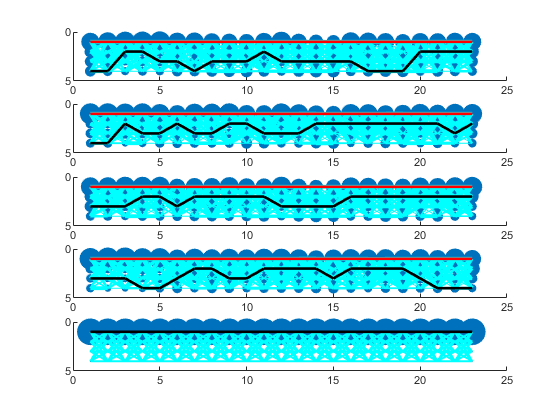

% https://kr.mathworks.com/help/matlab/ref/scatter.html
figure;

emission_plot = zeros(npair, 3, nbest * nframe);
for p = 1:npair
    for ibest = 1:nbest
        for iframe = 1:nframe
            emission_plot(p,1,(ibest-1) * nframe + iframe) = iframe;
            emission_plot(p,2,(ibest-1) * nframe + iframe) = ibest;
            emission_plot(p,3,(ibest-1) * nframe + iframe) = 1 + 400 * 10^(emission1(p, iframe, ibest));
        end
    end
end

hold on;
for p=1:npair
    subplot(npair,1,p);
    scatter(...
        squeeze(emission_plot(p, 1,:)), ... % x range (x data for scatter)
        squeeze(emission_plot(p, 2,:)), ... % y range (y data for scatter)
        squeeze(emission_plot(p, 3,:)), ... % radius
        'filled');     
    axis ij;
    ylim([0 nbest+1]); % for readability
end

hold on;
max_linewidth = 1+max(max(max(max(transition1))));
for p=1:npair
    subplot(npair, 1, p);
    for t = 2:nframe
        for n = 1:nbest
            for nprev = 1:nbest
                line([t-1 t], ... % x data
                    [nprev n], ... % y data
                    'LineWidth', 10^(transition1(p,t,n,nprev))*3,... % tuning
                    'Color','cyan');
            end
        end
    end
end

hold on;
for p = 1:npair
    subplot(npair,1,p);
    for t = 2:nframe
        line([t-1 t], [bestpath1(p,t-1,1) bestpath1(p,t,1)], ...
            'LineWidth', 2, ...
            'Color', 'red');
        line([t-1 t], [bestpath1(p,t-1,2) bestpath1(p,t,2)], ...
            'LineWidth', 2, ...
            'Color', 'black');
    end
end

## multi channel viterbi - state define

nbest2 = 2;
nstate = nbest2 ^ npair;
g = zeros(nstate, npair);
tmp_row = zeros(3,1);
l = 1;
for ibest = 1:nbest2
    [g, l] = fill_all_comb(1, npair, ibest, nbest2, tmp_row, g, l);
end
disp(g);

     1     1     1     1     1
     1     1     1     1     2
     1     1     1     2     1
     1     1     1     2     2
     1     1     2     1     1
     1     1     2     1     2
     1     1     2     2     1
     1     1     2     2     2
     1     2     1     1     1
     1     2     1     1     2
     1     2     1     2     1
     1     2     1     2     2
     1     2     2     1     1
     1     2     2     1     2
     1     2     2     2     1
     1     2     2     2     2
     2     1     1     1     1
     2     1     1     1     2
     2     1     1     2     1
     2     1     1     2     2
     2     1     2     1     1
     2     1     2     1     2
     2     1     2     2     1
     2     1     2     2     2
     2     2     1     1     1
     2     2     1     1     2
     2     2     1     2     1
     2     2     1     2     2
     2     2     2     1     1
     2     2     2     1     2
     2     2     2     2     1
     2     2     2     2     2



## multi channel viterbi - emission, trans prob

emission2 = zeros(nframe, nstate);
diff2 = zeros(nmic, nframe, nbest, nbest); % do not using 1st idx
transition2 = zeros(nframe, nstate, nstate); % do not using 1st idx

for t = 1:nframe
    for l = 1:nstate
        for m = 1:npair
            ibest = bestpath1(m, t, g(l,m));
            if gcc_nbest(m,t,ibest) > 0
                emission2(t, l)...
                    = emission2(t, l)...
                    + log10(gcc_nbest(m,t,ibest));
            end
            
        end
    end
end



for t = 2:nframe
    
    maxdiff2 = 0;
    for ibest = 1:nbest
        for jbest = 1:nbest
            for m = 1:npair-1 % why -1?
                diff2(m,t,ibest, jbest) = abs(tdoa_nbest(m,t,ibest) - tdoa_nbest(m,t-1,jbest));
                if maxdiff2 < diff2(m,t,ibest, jbest)
                    maxdiff2 = diff2(m,t,ibest, jbest);
                end
            end
        end
    end
    
    diff2(:,t,:,:) = log10( (1 + maxdiff2 - diff2(:,t,:,:)) / (2 + maxdiff2) );
    
    for l = 1:nstate
        for lprev = 1:nstate
            for m = 1:npair-1 % why -1?           
                ibest = bestpath1(m, t, g(l,m));
                jbest = bestpath1(m, t-1, g(lprev,m));
                
                transition2(t,l,lprev)...
                    = transition2(t,l,lprev)...
                    + diff2(m,t,ibest,jbest);
            end
        end
    end
           
end
disp(emission2(2,end));

  -4.125753482985052



disp(transition2(2,:,1));

  1 ~ 3번 열

  -0.023009315556365  -0.023009315556365  -0.065561666241829

  4 ~ 6번 열

  -0.065561666241829  -0.071995776247239  -0.071995776247239

  7 ~ 9번 열

  -0.114548126932703  -0.114548126932703  -0.052972538933809

  10 ~ 12번 열

  -0.052972538933809  -0.095524889619272  -0.095524889619272

  13 ~ 15번 열

  -0.101958999624682  -0.101958999624682  -0.144511350310146

  16 ~ 18번 열

  -0.144511350310146  -0.085157222305210  -0.085157222305210

  19 ~ 21번 열

  -0.127709572990673  -0.127709572990673  -0.134143682996083

  22 ~ 24번 열

  -0.134143682996083  -0.176696033681547  -0.176696033681547

  25 ~ 27번 열

  -0.115120445682653  -0.115120445682653  -0.157672796368117

  28 ~ 30번 열

  -0.157672796368117  -0.164106906373527  -0.164106906373527

  31 ~ 32번 열

  -0.206659257058990  -0.206659257058990



## multi channel viterbi - searching

back2_table = zeros(nframe, nstate);

bestpath2 = ones(nframe, 1); % state idx stored.

dC = ones(nframe, nstate) * -1000;
tC = ones(nframe, nstate);

R = ones(nframe, 1); % best prev state
F = ones(nframe, 1);

forwardTrans = zeros(nframe, nstate);
selfLoopTrans = zeros(nframe, nstate);


for l = 1:nstate
    dC(1,l) = emission2(1,l);
end


for t = 2:nframe
    for l = 1:nstate
        best_l_prev = R(t-1);
        back2_table(t,l) = best_l_prev;
        
        forwardTrans(t,l) = dC(t-1,best_l_prev) + 25 * transition2(t,l,best_l_prev);
        selfLoopTrans(t,l) = dC(t-1,l) + 25 * transition2(t,l,l);
        
        if selfLoopTrans(t,l) >= forwardTrans(t,l)
            dC(t,l) = selfLoopTrans(t,l) + emission2(t,l);
            tC(t,l) = tC(t-1,l);
        else
            dC(t,l) = forwardTrans(t,l) + emission2(t,l);
            tC(t,l) = t;
        end
    end
    
    [dummy, R(t)] = max(dC(t,:));
    F(t) = tC(t,R(t));
    
end

st = F(end);
bestpath2(st:end) = R(end);

while st > 2
    ed = st - 1;
    st = F(ed);
    bestpath2(st:ed) = R(ed);
end

viterbi_score = dC(end,R(end));

besttdoa = zeros(npair, nframe);
bestgcc2 = zeros(npair, nframe);

for t = 1:nframe
    for p = 1:npair
        l = bestpath2(t);
        ibest = bestpath1(p, t, g(l,p));
        besttdoa(p,t) = tdoa_nbest(p,t,ibest);
        bestgcc2(p,t) = gcc_nbest(p,t,ibest);
    end
end
disp(back2_table(:,:)'); % compare first mic pair trellis plot

  1 ~ 12번 열

     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1     1     1     1     1     1     1
     0     1     1     1     1     1  



disp(besttdoa);

  1 ~ 12번 열

     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0    -1     0
    -1    -1    -1    -1    -1     2     2    -1    -1     2     2    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1    -1
     0     0     0     0     0     0     0     0     0     0     0     0

  13 ~ 23번 열

     0     0     0     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     1     1
    -1    -1    -1     0     0     0     0     0     0     0     0
     1     1     1    -1    -1     1     1    -1    -1     0     2
     0     0     0     0     0     0     0     0     0     0     0



## multi channel viterbi - plot

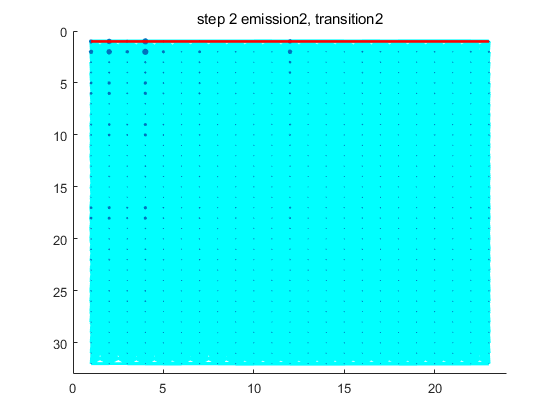

% https://kr.mathworks.com/help/matlab/ref/scatter.html
figure;

title(sprintf('step 2 emission2, transition2'));
for t = 2:nframe
    for l = 1:nstate
        for lprev = 1:nstate
            line([t-1 t], ... % x data
                [lprev l], ... % y data
                'LineWidth', 3*(exp(transition2(t,l,lprev))),... % tuning
                'Color','cyan');
            axis ij;
        end
    end
end

emission2_plot = zeros(3, nstate * nframe);

for l = 1:nstate
    for iframe = 1:nframe
        
       
        emission2_plot(1,(l-1) * nframe + iframe) = iframe;
        emission2_plot(2,(l-1) * nframe + iframe) = l;
        emission2_plot(3,(l-1) * nframe + iframe) = 1 + 400 * 10^(emission2(iframe, l));
    end
end

hold on;
scatter(...
    squeeze(emission2_plot(1,:)), ... % x range (x data for scatter)
    squeeze(emission2_plot(2,:)), ... % y range (y data for scatter)
    squeeze(emission2_plot(3,:)), ... % radius
    'filled');

hold on;
for t = 2:nframe
    line([t-1 t], [bestpath2(t-1) bestpath2(t)], ...
        'LineWidth', 2, ...
        'Color', 'red');
end


axis ij;
ylim([0 nstate+1]); % for readability
xlim([0 nframe+1]);

## compute local xcorr

tmp_localxcorr = zeros(nmic, nmic, nframe);
localxcorr = zeros(nmic, nframe);

mic2refpair = zeros(nmic,1);
mic2refpair(ref_mic) = 0;

for p = 1:npair
    m = micpair(ref_mic,p);
    mic2refpair(m) = p;
end

for t = 1:nframe
    ref_st = (t-1) * 4000 + 1;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m1 = 1:(nmic-1)
        for m2 = (m1+1):nmic
            
            if m1 == ref_mic
                st1 = ref_st;
                ed1 = ref_ed;
            else
                p = mic2refpair(m1);
                st1 = max(1,ref_st + besttdoa(p,t));
                ed1 = min(nsample, ref_ed + besttdoa(p,t));
            end
            
            if m2 == ref_mic
                st2 = ref_st;
                ed2 = ref_ed;
            else
                p = mic2refpair(m2);
                st2 = max(1,ref_st + besttdoa(p,t));
                ed2 = min(nsample, ref_ed + besttdoa(p,t));
            end
            
            buf1 = x(m1,st1:ed1);
            buf2 = x(m2,st2:ed2);
            
            ener1 = sum(buf1(:).^2);
            ener2 = sum(buf2(:).^2);
            
            min_ed = min(ed1-st1, ed2-st2) + 1;
            tmp_localxcorr(m1,m2,t)...
                = sum(...
                buf1(1:min_ed) .* buf2(1:min_ed)...
                / (ener1 * ener2));
            
            if tmp_localxcorr(m1,m2,t) < 0
                tmp_localxcorr(m1,m2,t) = 0;
            end
            
            tmp_localxcorr(m2,m1,t) = tmp_localxcorr(m1,m2,t);
        end
    end
end

disp(tmp_localxcorr(1,2:3,1));

   0.082733742063683   0.065330101365184




localxcorr = squeeze(sum(tmp_localxcorr,1));
disp(localxcorr);

  1 ~ 3번 열

   0.302169167981066   0.257919412970662   0.273903012056209
   0.650171006651072   0.435657858175634   0.454848175106291
   0.788425543828791   0.541218144188156   0.600360905574395
   0.778189960108224   0.546868804686471   0.589426051042608
   0.631014905344243   0.405230900288677   0.435396515443680

  4 ~ 6번 열

   0.258161252213678   0.320632557691673   0.436929325318937
   0.483629947604222   0.647342300596884   0.726643043572168
   0.676863669477485   0.942643315716571   1.008437035110010
   0.673530526054160   0.924738694092956   1.014453332871191
   0.504751386006962   0.686115949042530   0.751823857115864

  7 ~ 9번 열

   0.309546496906668   0.243376270842308   0.223985826121722
   0.507930272570137   0.494433681274898   0.532051918713833
   0.691160957573207   0.684385342166420   0.739485163195598
   0.694529940810026   0.644149346947561   0.707437820182765
   0.526041615673597   0.517648911571530   0.562247956032419

  10 ~ 12번 열

   0.287424253363942   0.3340369

## compute sum weight

out_weight = ones(nmic, nframe) * ( 1 / nmic);
alpha = 0.05;


for t = 1:nframe
    
    if sum(localxcorr(:,t)) == 0
        localxcorr(:,t) = 1 / nmic;
    end
    
    localxcorr(:,t) = localxcorr(:,t) / sum(localxcorr(:,t));
    localxcorr_sum_nonref = 0;
    localxcorr_sum = 0;
    
    for m = 1:nmic
        if m == ref_mic
             out_weight(m,t) = ...
            (1-alpha) * out_weight(m,max(1,t-1)) ...
            + alpha * localxcorr(m,t);    
        
        else
            p = mic2refpair(m);
            if noise_filter(p,t) == 0
                out_weight(m,t) = ...
                    (1-alpha) * out_weight(m,max(1,t-1)) ...
                    + alpha * localxcorr(m,t);    
            end
            
            localxcorr_sum_nonref = localxcorr_sum_nonref + localxcorr(m,t);
        end 
    end
    
    if sum(localxcorr(:,t)) == 0
        out_weight(:,t) = 1;
    end
    
    for m = 1:nmic
        if m ~= ref_mic
            if (localxcorr(m,t) / localxcorr_sum_nonref) < (1 / (10 * (nmic-1)))
                out_weight(m,t) = 0;
            end
        end
    end
    out_weight(:,t) = out_weight(:,t) / sum(out_weight(:,t));
    
end

disp(mic2refpair');

     1     2     3     4     5



disp(out_weight);

  1 ~ 3번 열

   0.194796380790415   0.190953493217231   0.187223801034834
   0.200320271083981   0.200264905713815   0.199913104795837
   0.202514808040672   0.204763189725287   0.207277315083083
   0.202352336940579   0.204738035858621   0.207021151321333
   0.200016203144353   0.199280375485045   0.198564627764913

  4 ~ 6번 열

   0.182833106492783   0.178243986063927   0.174878987489925
   0.199228995972504   0.198458903515131   0.197761328639765
   0.209945412107860   0.212832361183623   0.214993735124178
   0.209637882014292   0.212285986952500   0.214551061777641
   0.198354603412561   0.198178762284820   0.197814886968491

  7 ~ 9번 열

   0.171806030420311   0.167925033815678   0.192971747623457
   0.197178709679957   0.196887013261602   0.189752138026074
   0.216906341467719   0.219303807864595   0.213918689536994
   0.216547522655009   0.218184367770970   0.212333482292172
   0.197561395777005   0.197699777287154   0.191023942521303

  10 ~ 12번 열

   0.197626855674619   0.1960592

## Channel sum

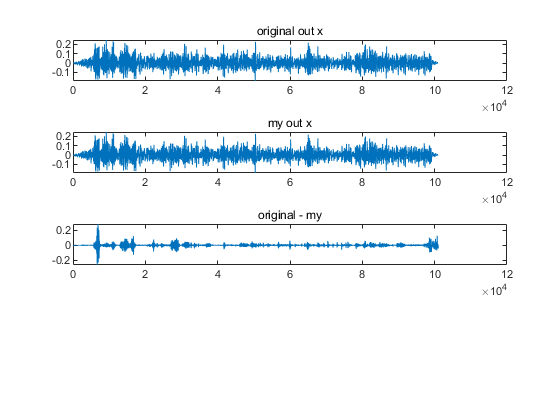

out_x = zeros(1,nsample);

% figure;
for t = 1:nframe
    ref_st = (t-1) * 4000 + 1;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m = 1:nmic   
        if m == ref_mic
            st = ref_st;
            ed = ref_ed;
        else
            p = mic2refpair(m);
            st = max(1,ref_st + besttdoa(p,t));
            ed = min(nsample, ref_ed + besttdoa(p,t));
        end
       
        triwin = triang(8000)';
%         if t == 1
%             triwin(1:4000) = 1;
%         end
        
         diff = 0;

        if (ref_ed - ref_st) ~= (ed - st) % if buf is small (always)
                diff = ref_ed - ed;
        end
        out_x(ref_st+diff:ref_ed)...
            = out_x(ref_st+diff:ref_ed)...   
            + (squeeze(x(m,st:ed))...
            * out_weight(m,t)...
            .* triwin(1:min(8000,ed-st+1))...
            * overall_weight);
            
        
            %.* triwin(min(8000,min_ed-ref_st+1))...
            %* out_weight(m,t));
%         plot(out_x);
    end
end


while ref_ed < nsample    
    ref_st = ref_st + 4000;
    ref_ed = min(ref_st + 8000 - 1, nsample);
    
    for m = 1:nmic
        if m == ref_mic
            st = ref_st;
            ed = ref_ed;
        else
            p = mic2refpair(m);
            st = max(1,ref_st + besttdoa(p,t));
            ed = min(nsample, ref_ed + besttdoa(p,t));
        end
        if st > ed
            continue;
        end
        buf = squeeze(x(m,st:ed));
        diff = (ref_ed - ref_st) - (ed-st);
        if diff > 0
            buf = [buf, zeros(1,diff)];
        else
            buf = buf(1:end-diff);
        end
        
        triwin = triang(8000)';
    
        out_x(ref_st:ref_ed)...
                = out_x(ref_st:ref_ed)...   
                + (buf...
                * out_weight(m,t)...
                .* triwin(1:min(8000,size(buf,2)))...
                * overall_weight);
    
    end
end



audiowrite(outname,out_x,16000);

out_x = audioread(outname);
orig_out_x = audioread(orig_outname);

subplot(4,1,1); plot(orig_out_x); title('original out x');
subplot(4,1,2); plot(orig_out_x); title('my out x');
subplot(4,1,3); plot(out_x-orig_out_x); title('original - my');


nshift = nwin / 2; % 4000
ed = (nframe-1)*nshift;
disp(mean((out_x-orig_out_x).^2));

     1.529338351735413e-04



function [table, l] = fill_all_comb(ipair, npair, ibest, nbest, tmp_row, table, l)
    tmp_row(ipair) = ibest;
    %fprintf('ipair: %d ibest: %d l: %d\n', ipair, ibest, l);
    
    if ipair == npair    
        for j = 1:npair
            table(l, j) = tmp_row(j);
        end
        l = l + 1;
    else
        for ibest = 1:nbest
            [table, l] = fill_all_comb(ipair + 1, npair, ibest, nbest, tmp_row, table, l);
        end
    end
end

function [max_val, idx] = maxk(list, k, nmask)
    candi_list = zeros(length(list(:)),1);
    for i = 2:(length(list(:))-1)
        if list(i-1) < list(i) && list(i+1) < list(i)
            candi_list(i) = list(i);
%             list(i-1) = -9999;
%             list(i+1) = -9999;
        end
    end

    max_val = zeros(k, 1);
    idx = zeros(k,1);
    for i = 1:k
        [max_val(i), idx(i)] = max(candi_list);
        st = max(idx(i)-nmask+1, 1);
        ed = min(length(candi_list(:)), idx(i)+nmask-1);
        candi_list(st:ed) = 0;
    end
end